%read data
im = cdata;

%reshape
im3column = reshape(im,[],3)

im3column = 1950464×3 uint8 matrix
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0


%find ROI
[~,inx] = ROI(im);
roi = im3column(inx,:)

roi = 1197940×3 uint8 matrix
   14    0    0
   15    2    0
   17    2    0
   19    1    0
   18    3    0
   17    3    0
   15    4    0
   13    2    0
   13    2    0
   13    2    0


%get the area not include vain and mecula
meanG = mean(double(roi(:,2)))

meanG = 35.4385

stdG = std(double(roi(:,2)))

stdG = 18.5202

meanSubStd = meanG - stdG

meanSubStd = 16.9183

meanAddStd = meanG + stdG

meanAddStd = 53.9586


roi2Inx = find((roi(:,2) >= meanSubStd & roi(:,2) <= meanAddStd));

X = roi(roi2Inx,:)

X = 991724×3 uint8 matrix
   44   17   10
   41   17    7
   45   18    9
   46   18    7
   45   18    7
   44   21    7
   43   21    7
   40   17    3
   41   17    7
   42   18    8


%Normalize X so X in range [0,1]
Xnew = double(X) / 255

Xnew =     0.1725    0.0667    0.0392
    0.1608    0.0667    0.0275
    0.1765    0.0706    0.0353
    0.1804    0.0706    0.0275
    0.1765    0.0706    0.0275
    0.1725    0.0824    0.0275
    0.1686    0.0824    0.0275
    0.1569    0.0667    0.0118
    0.1608    0.0667    0.0275
    0.1647    0.0706    0.0314


%calculate variable Q or SIGMA_target
Q = std(Xnew)

Q =     0.0935    0.0344    0.0112


Q(2) = Q(1)

Q =     0.0935    0.0935    0.0112


Q = diag(Q)

Q =     0.0935         0         0
         0    0.0935         0
         0         0    0.0112


%calculate eigenvector and eigenvalue
covs = cov(Xnew)

covs =     0.0088    0.0028    0.0005
    0.0028    0.0012    0.0003
    0.0005    0.0003    0.0001


[U,D] = svd(covs)

U =    -0.9491    0.3065    0.0729
   -0.3093   -0.8628   -0.3999
   -0.0597   -0.4021    0.9137


D =     0.0097         0         0
         0    0.0003         0
         0         0    0.0000


%calculate scale to stretch
E = diag([1 1 0]);
sc = (D * E).^(-1/2)

sc =    10.1642       Inf       Inf
       Inf   54.4134       Inf
       Inf       Inf       Inf


sc(isinf(sc) | isnan(sc)) = 0

sc =    10.1642         0         0
         0   54.4134         0
         0         0         0


%calculate T transformation function
T = U * sc * U' * Q

T =     1.3346   -1.0668   -0.0688
   -1.0668    3.8800    0.2139
   -0.5734    1.7834    0.0991


%set m(ean)_target
C = (double([192 96 32]) / 255)

C =     0.7529    0.3765    0.1255


%improve quality of input something
roi = medfilt3(roi,[3,3,3]);

%Normalize the whole roi area
B = double(roi)/255

B =     0.0549         0         0
    0.0549    0.0078         0
    0.0588    0.0078         0
    0.0667    0.0078         0
    0.0667    0.0118         0
    0.0588    0.0118         0
    0.0510    0.0118         0
    0.0510    0.0078         0
    0.0510    0.0078         0
    0.0510    0.0078         0


%calculate the roi mean
meanB = mean(B)

meanB =     0.3638    0.1390    0.0354


%resemble all together to get the output
G = (B - meanB) * T

G =    -0.2436   -0.2729   -0.0120
   -0.2520   -0.2425   -0.0103
   -0.2468   -0.2466   -0.0106
   -0.2363   -0.2550   -0.0111
   -0.2405   -0.2398   -0.0103
   -0.2509   -0.2314   -0.0097
   -0.2614   -0.2231   -0.0092
   -0.2572   -0.2383   -0.0100
   -0.2572   -0.2383   -0.0100
   -0.2572   -0.2383   -0.0100


%
rgb = G * 255

rgb =   -62.1241  -69.5886   -3.0584
  -64.2577  -61.8285   -2.6307
  -62.9232  -62.8953   -2.6994
  -60.2540  -65.0290   -2.8370
  -61.3208  -61.1490   -2.6231
  -63.9900  -59.0153   -2.4856
  -66.6591  -56.8816   -2.3480
  -65.5923  -60.7617   -2.5619
  -65.5923  -60.7617   -2.5619
  -65.5923  -60.7617   -2.5619


%check mean of G
meanRGB = mean(rgb)

meanRGB = 	1.0e+-9 *

    0.0376   -0.2390   -0.0129


stdRGB = std(rgb)

stdRGB =    27.9784   50.4353    2.5401


MaxRGB = max(rgb)

MaxRGB =   135.4923  619.9710   32.6711


MinRGB = min(rgb)

MinRGB =   -81.9524 -104.6075   -6.4774


%display part
im3column(inx,:) = uint8(rgb)

im3column = 1950464×3 uint8 matrix
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0


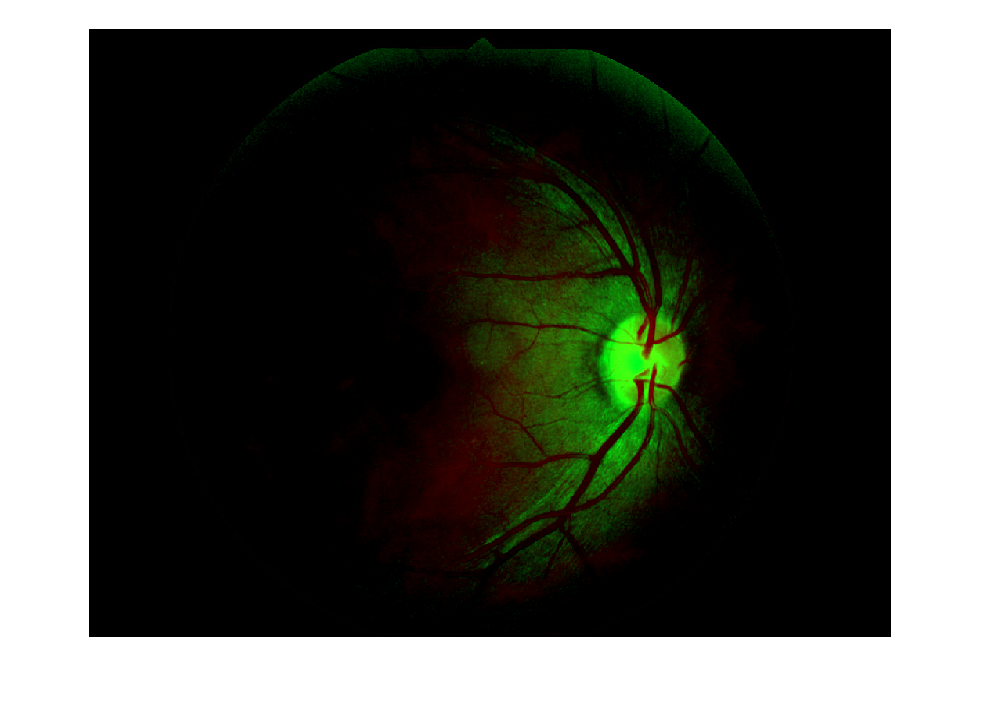

dis = reshape(im3column,size(im));
imshow(dis)

%add m_target
G = G + C

G =     0.5093    0.1036    0.1135
    0.5010    0.1340    0.1152
    0.5062    0.1298    0.1149
    0.5167    0.1215    0.1144
    0.5125    0.1367    0.1152
    0.5020    0.1450    0.1157
    0.4915    0.1534    0.1163
    0.4957    0.1382    0.1154
    0.4957    0.1382    0.1154
    0.4957    0.1382    0.1154


%back to range 0-255
rgb = G*255

rgb =   129.8759   26.4114   28.9416
  127.7423   34.1715   29.3693
  129.0768   33.1047   29.3006
  131.7460   30.9710   29.1630
  130.6792   34.8510   29.3769
  128.0100   36.9847   29.5144
  125.3409   39.1184   29.6520
  126.4077   35.2383   29.4381
  126.4077   35.2383   29.4381
  126.4077   35.2383   29.4381


%check mean of G
meanRGB = mean(rgb)

meanRGB =   192.0000   96.0000   32.0000


stdRGB = std(rgb)

stdRGB =    27.9784   50.4353    2.5401


MaxRGB = max(rgb)

MaxRGB =   327.4923  715.9710   64.6711


MinRGB = min(rgb)

MinRGB =   110.0476   -8.6075   25.5226


%display part
im3column(inx,:) = uint8(rgb)

im3column = 1950464×3 uint8 matrix
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0


dis = reshape(im3column,size(im))

dis = 1216×1604×3 uint8 array
dis(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

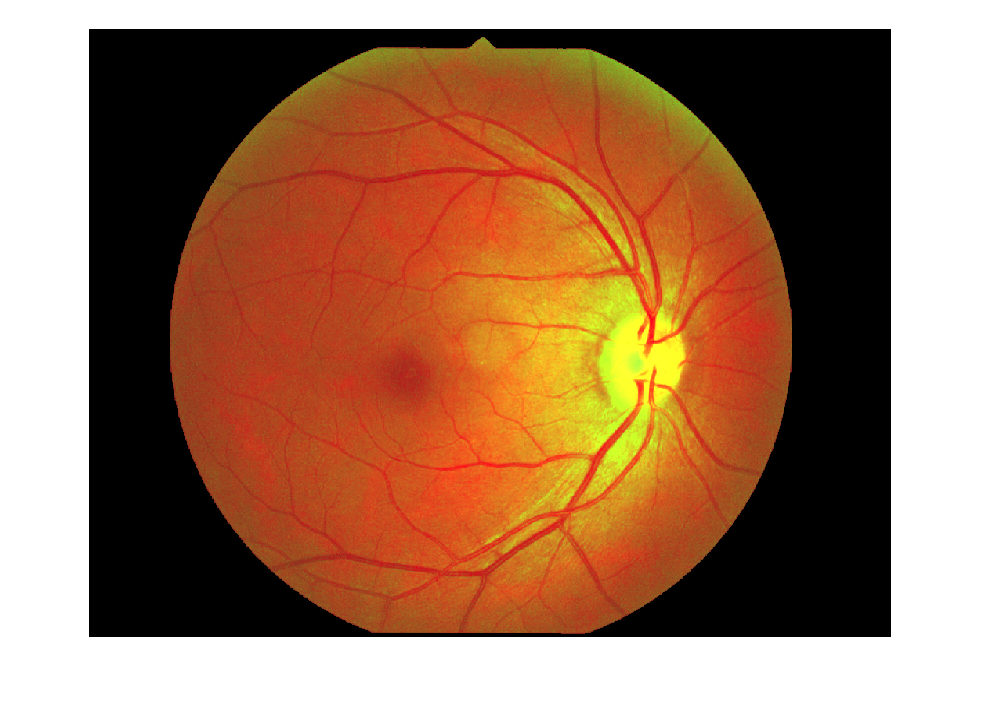

imshow(dis)